# Fourth part - 3 dof system with a sine sweeep input

close all; clear all; clc;

load('data_3dof_sine_sweep.mat');

Note we directly convert the input signal from a voltage to a force easly by multiplying with a given constant.

input_signal = data_3dof(:,1)*0.04*0.01;    % [N]
time = data_3dof(:,2);                      % [s]
out1 = data_3dof(:,3)*0.01;                 % [m]
out2 = data_3dof(:,4)*0.01;                 % [m]
out3 = data_3dof(:,5)*0.01;                 % [m]

number_of_samples = size(out1,1);
total_time = max(time);
fs = number_of_samples/total_time;

## 4.1 Equation of motion

First we summarize the constant found in the previous experiments:

m1 = 1.7;                   % [kg]
k0 = 400.34;                % [N/m]
c1 = 3.08;                  % [N s/m]
m_cart = 0.72;              % [kg]
m_disk = 0.49;              % [kg]
m2 = m_cart + 3*m_disk;     % [kg]
m3 = m2;                    % [kg]

We can write respectively the mass,  damping and stiffness matrices.

We know k1, k2, c2 and c3 to be unknowns of our problem.

syms k1 k2 c2 c3 s
M = [m1 0  0  ;
     0  m2 0  ;
     0  0  m3];
C = [c1 0  0  ;
     0  c2 0  ;
     0  0  c3];
K = [k0+k1  -k1   0  ;
      -k1  k2+k1 -k2 ;
       0    -k2   k2];

## 4.2 Experimental transfer function

Now we estimate the Transfer Functions between each cart position and the force.

[Tf1, Fr1] = tfestimate(input_signal, out1, [], [], [], fs);
[Tf2, Fr2] = tfestimate(input_signal, out2, [], [], [], fs);
[Tf3, Fr3] = tfestimate(input_signal, out3, [], [], [], fs);

Estimate magnitude and phase for each transfer function:

Tm1 = abs(Tf1);
Tm_phase1 = unwrap(angle(Tf1));
Tm2 = abs(Tf2);
Tm_phase2 = unwrap(angle(Tf2));
Tm3 = abs(Tf3);
Tm_phase3 = unwrap(angle(Tf3));

Let's take a look to the Transfer functions:

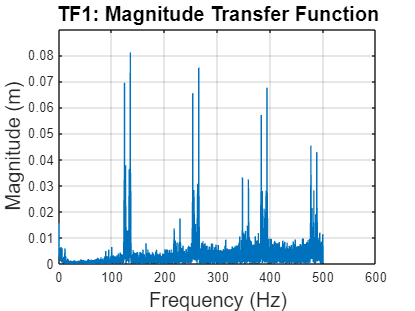

figure(8), clf;
plot(Fr1, Tm1);
xlabel('Frequency (Hz)','FontSize',15);
ylabel('Magnitude (m)','FontSize',15);
title('TF1: Magnitude Transfer Function','FontSize',15);
grid on;

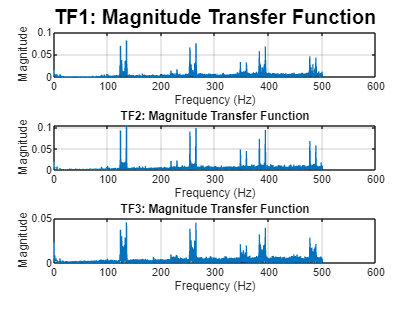


figure(1), clf;
subplot(3,1,1);
plot(Fr1, Tm1);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('TF1: Magnitude Transfer Function','FontSize',15);
grid on;

subplot(3,1,2);
plot(Fr2, Tm2);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('TF2: Magnitude Transfer Function');
grid on;

subplot(3,1,3);
plot(Fr3, Tm3);
xlabel('Frequency (Hz)');
ylabel('Magnitude');
title('TF3: Magnitude Transfer Function');
grid on;

We can clearly see the plots are overcrowded, we expect the natural frequency to have a small value, so for example we can consider to truncate the data to the first 200 samples in frequency domain:

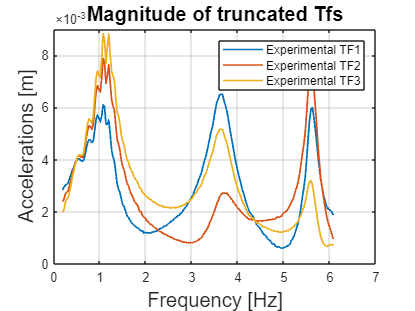

L = 200;
Tf1_trunc = Tf1(7:L,:);
Fr1_trunc = Fr1(7:L,:);
Tm1_trunc = abs(Tf1_trunc); % real vector 
Tm1_phase_trunc = unwrap(angle(Tf1_trunc)); % phase

Tf2_trunc = Tf2(7:L,:);
Fr2_trunc = Fr2(7:L,:);
Tm2_trunc = abs(Tf2_trunc); % real vector 
Tm2_phase_trunc = unwrap(angle(Tf2_trunc)); % phase

Tf3_trunc = Tf3(7:L,:);
Fr3_trunc = Fr3(7:L,:);
Tm3_trunc = abs(Tf3_trunc); % real vector 
Tm3_phase_trunc = unwrap(angle(Tf3_trunc)); % phase

figure(2),clf
plot(Fr1_trunc, Tm1_trunc,'LineWidth',1.3)
hold on
plot(Fr2_trunc, Tm2_trunc,'LineWidth',1.3)
plot(Fr3_trunc, Tm3_trunc,'LineWidth',1.3)
xlabel('Frequency [Hz]','FontSize',15)
ylabel('Accelerations [m]','FontSize',15)
legend('Experimental TF1', 'Experimental TF2','Experimental TF3');
title('Magnitude of truncated Tfs','FontSize',15)
grid on

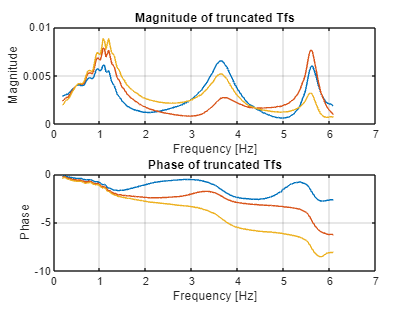


figure(7),clf
subplot(2,1,1)
plot(Fr1_trunc, Tm1_trunc)
hold on
plot(Fr2_trunc, Tm2_trunc)
plot(Fr3_trunc, Tm3_trunc)
xlabel('Frequency [Hz]')
ylabel('Magnitude')
title('Magnitude of truncated Tfs')
grid on

subplot(2,1,2)
plot(Fr1_trunc, Tm1_phase_trunc)
hold on
plot(Fr2_trunc, Tm2_phase_trunc)
plot(Fr3_trunc, Tm3_phase_trunc)
xlabel('Frequency [Hz]')
ylabel('Phase')
title('Phase of truncated Tfs')
grid on

## 4.3 Analytical Transfer Function

% T_an = ([m1 0  0;
%          0  m2 0;
%          0  0  m3].*s.^2 + ...
%         [c1 0  0;
%          0  c2 0;
%          0  0  c3].*s + ...
%         [k0+k1  -k1   0  ;
%           -k1  k2+k1 -k2 ;
%            0    -k2   k2])^(-1);

T_an = (M.*s^2 + C.*s + K)^(-1);

w_rng = Fr1_trunc*2*pi;             % from [Hz] to [rad/s]
s = sqrt(-1)*w_rng;

% T1_fun = matlabFunction(T_an(1,1));
% T1_fun1 = @(c2,c3,k1,k2)T1_fun(c2,c3,k1,k2,sqrt(-1)*w_rng);
% T2_fun = matlabFunction(T_an(2,1));
% T2_fun1 = @(c2,c3,k1,k2)T2_fun(c2,c3,k1,k2,sqrt(-1)*w_rng);
% T3_fun = matlabFunction(T_an(3,1));
% T3_fun1 = @(c2,c3,k1,k2)T3_fun(c2,c3,k1,k2,sqrt(-1)*w_rng);

T1_fun = @(k1,k2,c2,c3)(20*(25*k1*k2 + 55*c2*s.^3 + 55*c3*s.^3 + 55*k1*s.^2 + 110*k2*s.^2 + 121*s.^4 + 25*c2*k2*s + 25*c3*k1*s + 25*c3*k2*s + 25*c2*c3*s.^2))./(200000*k1*k2 + 440000*c2*s.^3 + 2145*c2*s.^4 + 440000*c3*s.^3 + 1870*c2*s.^5 + 2145*c3*s.^4 + 1870*c3*s.^5 + 440000*k1*s.^2 + 2145*k1*s.^3 + 880000*k2*s.^2 + 4290*k1*s.^4 + 4290*k2*s.^3 + 3740*k2*s.^4 + 968000*s.^4 + 4719*s.^5 + 4114*s.^6 + 3050*k1*k2*s.^2 + 200000*c2*k2*s + 200000*c3*k1*s + 200000*c3*k2*s + 975*k1*k2*s + 200000*c2*c3*s.^2 + 975*c2*c3*s.^3 + 850*c2*c3*s.^4 + 1100*c2*k1*s.^3 + 975*c2*k2*s.^2 + 975*c3*k1*s.^2 + 850*c2*k2*s.^3 + 1950*c3*k1*s.^3 + 975*c3*k2*s.^2 + 850*c3*k2*s.^3 + 500*c2*k1*k2*s + 500*c3*k1*k2*s + 500*c2*c3*k1*s.^2);
T2_fun = @(k1,k2,c2,c3)(100*k1*(11*s.^2 + 5*c3*s + 5*k2))./(200000*k1*k2 + 440000*c2*s.^3 + 2145*c2*s.^4 + 440000*c3*s.^3 + 1870*c2*s.^5 + 2145*c3*s.^4 + 1870*c3*s.^5 + 440000*k1*s.^2 + 2145*k1*s.^3 + 880000*k2*s.^2 + 4290*k1*s.^4 + 4290*k2*s.^3 + 3740*k2*s.^4 + 968000*s.^4 + 4719*s.^5 + 4114*s.^6 + 3050*k1*k2*s.^2 + 200000*c2*k2*s + 200000*c3*k1*s + 200000*c3*k2*s + 975*k1*k2*s + 200000*c2*c3*s.^2 + 975*c2*c3*s.^3 + 850*c2*c3*s.^4 + 1100*c2*k1*s.^3 + 975*c2*k2*s.^2 + 975*c3*k1*s.^2 + 850*c2*k2*s.^3 + 1950*c3*k1*s.^3 + 975*c3*k2*s.^2 + 850*c3*k2*s.^3 + 500*c2*k1*k2*s + 500*c3*k1*k2*s + 500*c2*c3*k1*s.^2);
T3_fun = @(k1,k2,c2,c3)(500*k1*k2)./(200000*k1*k2 + 440000*c2*s.^3 + 2145*c2*s.^4 + 440000*c3*s.^3 + 1870*c2*s.^5 + 2145*c3*s.^4 + 1870*c3*s.^5 + 440000*k1*s.^2 + 2145*k1*s.^3 + 880000*k2*s.^2 + 4290*k1*s.^4 + 4290*k2*s.^3 + 3740*k2*s.^4 + 968000*s.^4 + 4719*s.^5 + 4114*s.^6 + 3050*k1*k2*s.^2 + 200000*c2*k2*s + 200000*c3*k1*s + 200000*c3*k2*s + 975*k1*k2*s + 200000*c2*c3*s.^2 + 975*c2*c3*s.^3 + 850*c2*c3*s.^4 + 1100*c2*k1*s.^3 + 975*c2*k2*s.^2 + 975*c3*k1*s.^2 + 850*c2*k2*s.^3 + 1950*c3*k1*s.^3 + 975*c3*k2*s.^2 + 850*c3*k2*s.^3 + 500*c2*k1*k2*s + 500*c3*k1*k2*s + 500*c2*c3*k1*s.^2);

err = @(x)rms(  Tm1_trunc - abs(T1_fun(x(1), x(2), x(3), x(4))) ...
              + Tm2_trunc - abs(T2_fun(x(1), x(2), x(3), x(4))) ...
              + Tm3_trunc - abs(T3_fun(x(1), x(2), x(3), x(4))));


x0 = [700 600 2 10];

x_opt = fminsearch(err, x0);

disp(' '); 

disp(' ANALYTICAL TF FIT RESULTS ');

 ANALYTICAL TF FIT RESULTS 


disp(['k1 fit value: ', num2str(x_opt(1)), ' N/m']);

k1 fit value: 829.3378 N/m


disp(['k2 fit value: ', num2str(x_opt(2)), ' N/m']);

k2 fit value: 780.7523 N/m


disp(['c2 fit value: ', num2str(x_opt(3)), ' Ns/m']);

c2 fit value: 0.4375 Ns/m


disp(['c3 fit value: ', num2str(x_opt(4)), ' Ns/m']);

c3 fit value: 8.0772 Ns/m


Now we can plot the analytical Transfer function

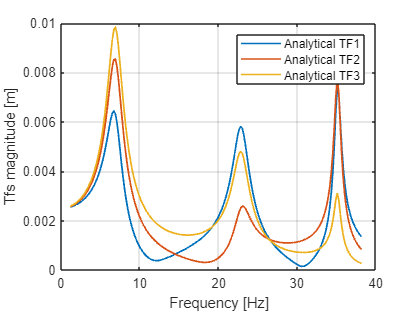

mod_T1_fun = abs(T1_fun(x_opt(1), x_opt(2), x_opt(3), x_opt(4)));
mod_T2_fun = abs(T2_fun(x_opt(1), x_opt(2), x_opt(3), x_opt(4)));
mod_T3_fun = abs(T3_fun(x_opt(1), x_opt(2), x_opt(3), x_opt(4)));

figure(3), clf
%title ('Analytical Transfer Functions' ) 
plot (w_rng, mod_T1_fun, 'LineWidth',1.3);
hold on;
plot (w_rng, mod_T2_fun, 'LineWidth',1.3);
plot (w_rng, mod_T3_fun, 'LineWidth',1.3);
xlabel('Frequency [Hz]');
ylabel('Tfs magnitude [m]');
legend('Analytical TF1', 'Analytical TF2', 'Analytical TF3');
grid on;
hold off;

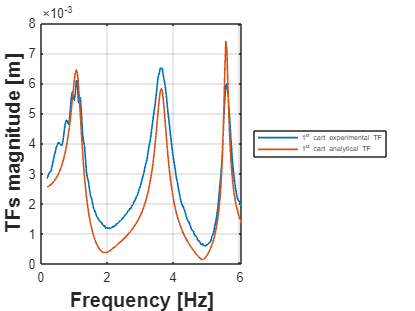


figure(4), clf
plot(Fr1_trunc, Tm1_trunc, 'LineWidth',1.2);
hold on;
plot(Fr1_trunc, mod_T1_fun, 'LineWidth',1.2);
xlabel("Frequency [Hz]", 'FontWeight', 'bold','FontSize',15);
ylabel("TFs magnitude [m]", 'FontWeight', 'bold','FontSize',15)
legend('1^{st} cart experimental TF', '1^{st} cart analytical TF','FontSize',5)
legend('Location','eastoutside');
grid on;
hold off;

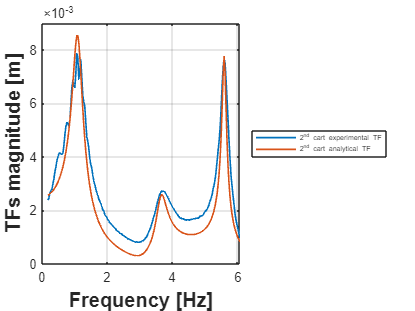


figure(5), clf
plot(Fr2_trunc, Tm2_trunc, 'LineWidth',1.2);
hold on;
plot(Fr2_trunc, mod_T2_fun, 'LineWidth',1.2);
xlabel("Frequency [Hz]", 'FontWeight', 'bold','FontSize',15);
ylabel("TFs magnitude [m]", 'FontWeight', 'bold','FontSize',15)
legend('2^{nd} cart experimental TF', '2^{nd} cart analytical TF','FontSize',5)
legend('Location','eastoutside');
grid on;
hold off;

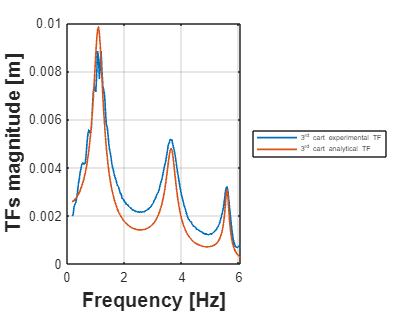


figure(6), clf
plot(Fr3_trunc, Tm3_trunc, 'LineWidth',1.2);
hold on;
plot(Fr3_trunc, mod_T3_fun,'LineWidth',1.2);
xlabel("Frequency [Hz]", 'FontWeight', 'bold','FontSize',15);
ylabel("TFs magnitude [m]", 'FontWeight', 'bold','FontSize',15)
legend('3^{rd} cart experimental TF', '3^{rd} cart analytical TF','FontSize',5)
legend('Location','eastoutside');
grid on;
hold off;